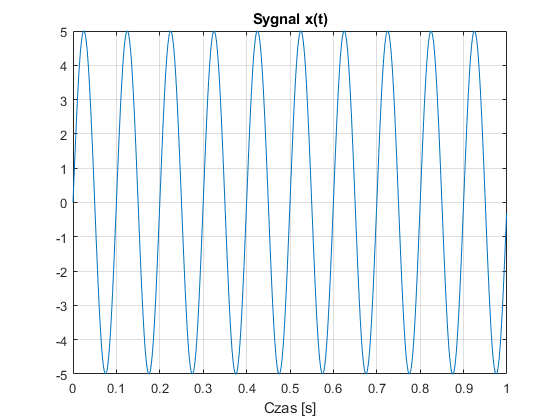

% Skrypt wywolania funkcji wyznaczających parametry sygnalow dyskretnych.

% Z przykladu zielinskiego - sprawdzenie wynikow
N=1000; A=5; fx=10; fp=1000;   %parametry sygnalu
dt = 1/fp;                      %okres probkowania
t = dt*(0:N-1);                 %wektor czasu
x = A*sin(2*pi*fx*t);           % sygnal
plot(t, x); grid; title('Sygnal x(t)'); xlabel('Czas [s]');


%  Obliczenie parametrow sygnalu
x_sred = mean(x), x_sred1 = signal_mean(x)

x_sred = -8.4438e-16

x_sred1 = -8.4438e-16

x_max = max(x), x_max = signal_max(x)

x_max = 5

x_max = 5

x_min = min(x), x_min2 = signal_min(x)

x_min = -5

x_min2 = -5

x_std1 = std(x), x_std2 = signal_std(x)

x_std1 = 3.5373

x_std2 = 3.5373

x_eng = dt*sum(x.^2), x_eng2 = signal_energy(x, dt)

x_eng = 12.5000

x_eng2 = 12.5000

x_moc = 1/N * x_eng, x_moc2 = signal_power(x, dt)

x_moc = 0.0125

x_moc2 = 0.0125

x_skut = sqrt(x_moc), x_rms2 = signal_rms(x, dt)

x_skut = 0.1118

x_rms2 = 0.1118

x_var = signal_var(x) % wariancja

x_var = 12.5125

x_nor_mom1 = signal_normal_momentum(x, 1), x_nor_mom2 = signal_normal_momentum(x, 2), x_nor_mom3 = signal_normal_momentum(x, 3)

x_nor_mom1 = -7.9551e+04

x_nor_mom2 = -7.9710e+07

x_nor_mom3 = -7.9669e+10

x_cen_mom1 = signal_central_momentum(x, 1), x_cen_mom2 = signal_central_momentum(x, 2), x_cen_mom3 = signal_central_momentum(x, 3)

x_cen_mom1 = -7.9551e+04

x_cen_mom2 = -1.2737e+10

x_cen_mom3 = -1.5294e+15

x_nor_mon_n1 = signal_normal_momentum_normalized(x, 1), x_nor_mon_n2 = signal_normal_momentum_normalized(x, 2), x_nor_mon_n3 = signal_normal_momentum_normalized(x, 3)

x_nor_mon_n1 = 9.4213e+16

x_nor_mon_n2 = 9.4401e+19

x_nor_mon_n3 = 9.4352e+22

x_cen_mon_n1 = signal_central_momentum_normalized(x, 1), x_cen_mon_n2 = signal_central_momentum_normalized(x, 2), x_cen_mon_n3 = signal_central_momentum_normalized(x, 3)

x_cen_mon_n1 = 5.2052e+16

x_cen_mon_n2 = -1.4706e+34

x_cen_mon_n3 = 2.2157e+51

x_cwq = signal_cwq(x)

x_cwq = 501.0000

x_vsqacwq_xD = signal_vsqacwq(x)

x_vsqacwq_xD = 8.3207e+04

x_rs = signal_rs(x)

x_rs = 288.4557

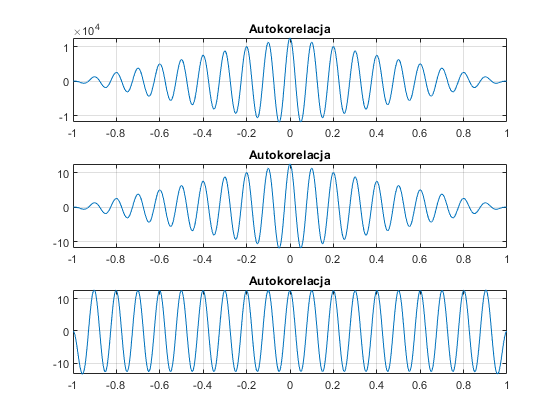


% Obliczenie korelacji R1, R2 i R3 syganlu
R1 = xcorr(x);              % korelacja nie umormowana
R2 = xcorr(x, 'biased');    % unormowana przez dlugosc /N
R3 = xcorr(x, 'unbiased');  % unormowana przez /(N-abs(k))
tR = [-fliplr(t) t(2:N)]; R = [R1; R2; R3];
for i=1:3
    subplot(3, 1, i);
    plot(tR, R(i, :)); grid; title('Autokorelacja');
end

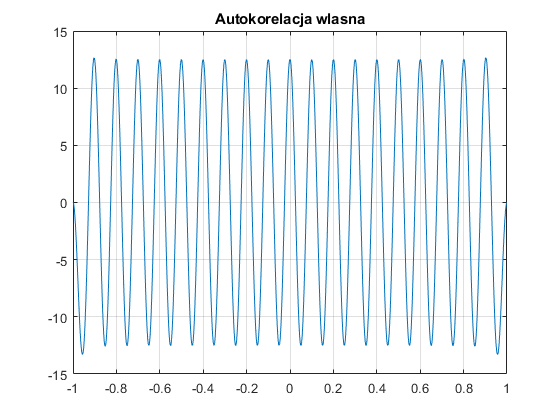


% wyznaczenie autokorelacji samemu
R_w = zeros(size(x));
for k=0:N-1
    R_w(k+1) = sum( x(1:N-k).*x(1+k:N) ) / (N-k);
end
R_w = [fliplr(R_w) R_w(2:N)];
figure();
plot(tR, R_w); grid; title('Autokorelacja wlasna');

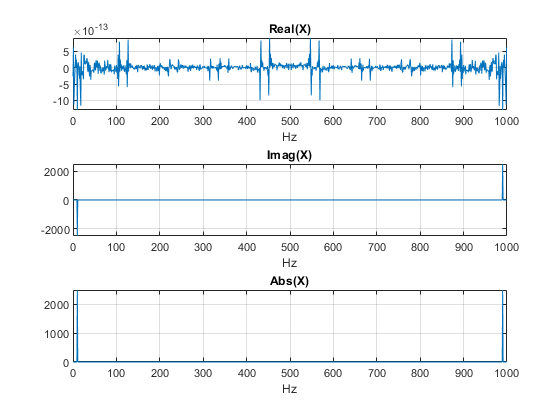


% obliczenia wspolczynnikow szeregu Fouriera sygnalu

X = fft(x);                 % szybka dyskretna transf Fouriera
df = 1/(N*dt);              % czestotliwosc podstawowa f0=df=1/T
f = df * (0:N-1);
subplot(3,1,1); plot(f, real(X)); grid; title('Real(X)'); xlabel('Hz');
subplot(3,1,2); plot(f, imag(X)); grid; title('Imag(X)'); xlabel('Hz');
subplot(3,1,3); plot(f, abs(X)); grid; title('Abs(X)'); xlabel('Hz');

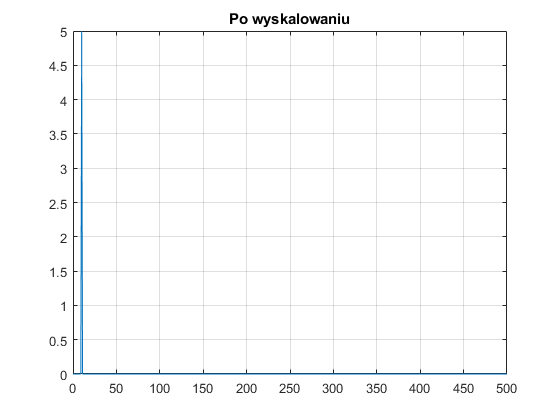

figure();
plot(f(1:N/2+1), abs(X(1:N/2+1))/(N/2) ); grid; title('Po wyskalowaniu');

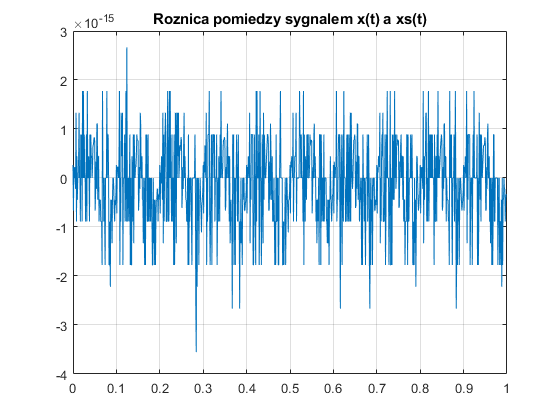


% zsyntezuj sygnal na podstawie wspolczynnikow szeregu i porownaj z
% orginalem
xs = ifft(X);
figure();
plot(t, real(x-xs)); grid; title('Roznica pomiedzy sygnalem x(t) a xs(t)');